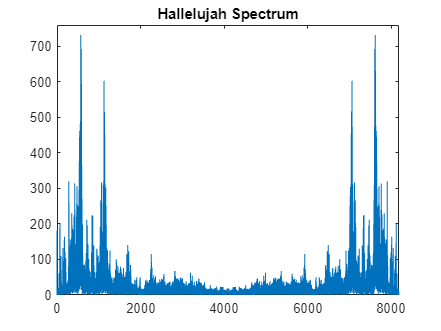

% Starting point for PV processing
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760]) 


% Call function to take STFTs of sequence PVAnalysis() 
[Moduli, Phase] = PVAnalysis(x, 512, 256);  

Window Size: 512
Hop Size: 256
# Windows: 255

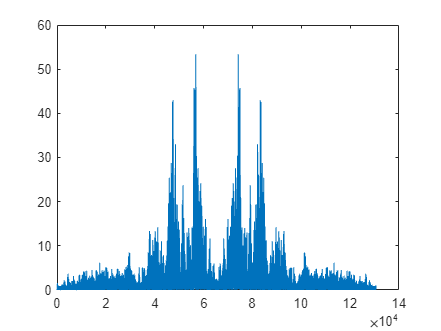

temp = reshape(Moduli, 1, []);
plot(temp) 

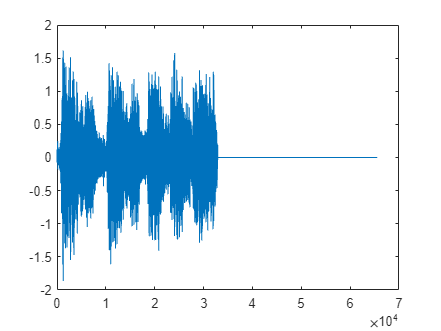

y = PVSynthesis(Moduli, Phase, 256, 128); 
plot(y)